clear;
mu = 0.07; 
sigma = 0.1; 
Xzero = 1; % problem parameters
dt = 0.001;
Xthresh = 2; %threshold for function to stop
X0 = Xzero;
r = 0.5;
n = 500;

Z = 0.5>=rand;
Z

Z = logical
   0


randn

ans = -0.6739

g = zeros(2,16);
g(:,1)

ans =      0
     0


Simulate income path using srGBM and plot

clear g;
% Simulate income path
Xtemp = Xzero;
i = 0;
pz = r*dt;

% preallocate array
g = zeros(2,2);
while Xtemp < Xthresh
    Z = pz >= rand;
    dW = sqrt(2*dt)*randn;
    Xtemp = Xtemp + (1-Z)*Xtemp*(mu*dt+sigma*dW)+Z*(Xzero-Xtemp);
    
    i = i+1;
    g(:,i) = [i*dt Xtemp]';
    if size(g(1,:)) == i
       %resize array
       g = [g,zeros(2,i)]; 
    end
end

g

g =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500
    1.0214    1.0054    1.0177    1.0593    1.0756    1.1045    1.0123    1.0156    0.9044    0.9179    0.9871    0.9154    0.9004    0.8998    0.9081    0.9102    0.8832    0.8859    0.8655    0.8960    0.8853    0.8822    0.8614    0.9128    0.9004    0.8876    0.8784    0.9544    0.8834    0.8601    0.9081    0.8728    0.8771    0.8270    0.8402    0.8471    0.8362    0.8509    0.8044    0.8338    0.8785    0.9044    0.8588    0.8569    0.8622    0.8692    0.8801    0.8731    0.8278    0

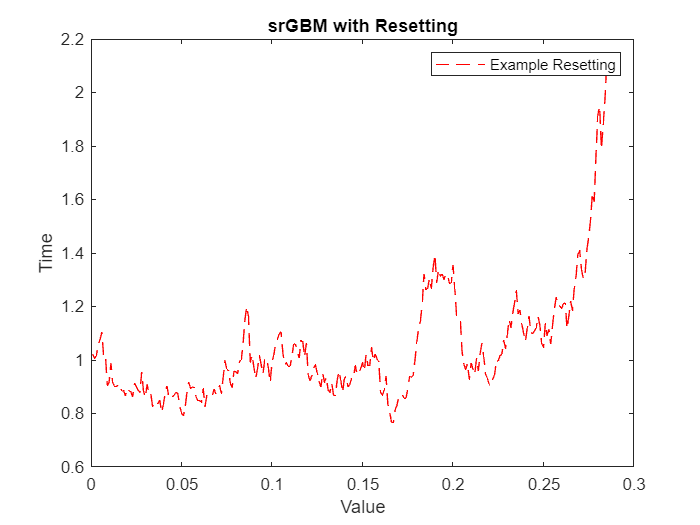

plot(g(1,:),g(2,:),'--r')
hold on

title("srGBM with Resetting") 
xlabel("Value")
ylabel("Time")
legend('Example Resetting')
hold off